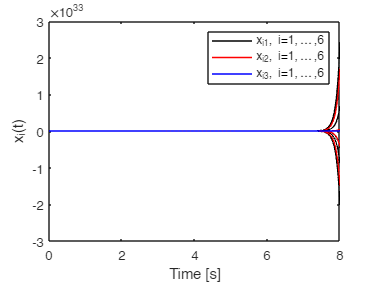

global L theta d n n_a
n = 6; 
n_a = 1; 
m = 8;
d = 3;
size = 1;
rng(3);

s = [1 1 2 2 3 3 4 5];
t = [2 4 3 5 4 6 5 6];
G = graph(s,t);
H = incidence(G)'*eye(6);
A12 = [1 0 0; 0 2 1; 0 1 2];
A25 = eye(3); A34 = A25;
A14 = [2 2 0; 2 2 0; 0 0 1];
A36 = A14;
A23 = [2 0 0; 0 0 0; 0 0 1];
A56 = A23;
A45 = [0 0 0; 0 1 0; 0 0 2];

W = blkdiag(A12,A14,A23,A25,A34,A36,A45,A56);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
x0 = [0;0;0;0;1;0;0;0;1;4*(rand(d*(n-3),1)-0.5)];
r0 = [x0;zeros(d*(n-n_a),1);zeros(d*(n-n_a),1)];
options = odeset('RelTol',1e-7,'AbsTol',1e-6);

% Consensus
[t,r] = ode45(@wv_consensus,[0:0.01:8],r0,options);
r = r';
x = r(1:d*n,:);
dx = r(d*n+1:d*n+d*(n-n_a),:);

e = zeros(length(t),1);
for i=1:length(t)
    e(i,1) = norm(L*x(:,i));
end

figure
hold on;
for i=1:n
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i(t)';
box on;
legend({'x_{i1}, i=1,\ldots,6','x_{i2}, i=1,\ldots,6','x_{i3}, i=1,\ldots,6'},"NumColumns",1)

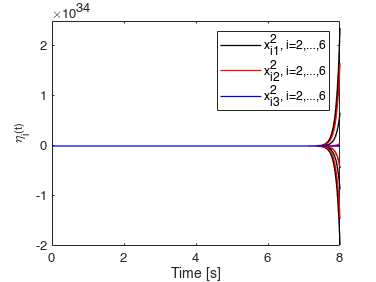


figure
hold on;
for i=1:n-n_a
   plot(t,dx(3*i-2,:),'-k','LineWidth',1);
   plot(t,dx(3*i-1,:),'-r','LineWidth',1);
   plot(t,dx(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel '\eta_i(t)';
box on;
legend({'x_{i1}^2, i=2,\ldots,6','x_{i2}^2, i=2,\ldots,6','x_{i3}^2, i=2,\ldots,6'},"NumColumns",1)

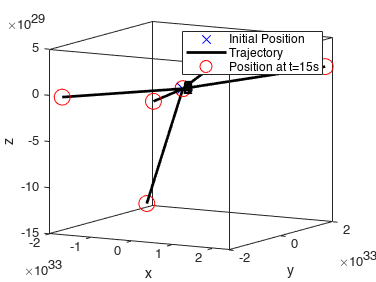


figure
hold on;
for i=1:n
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',2);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
ax = gca;
ax.BoxStyle = 'full';
box on
legend({'Initial Position','Trajectory','Position at t=15s'}, "NumColumns", 1)
view(30,10)

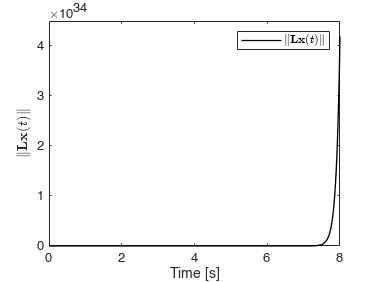


figure
hold on;
plot(t,e,'-k','LineWidth',1);
xlabel 'Time [s]'; ylabel('$\|\mathbf{L}\mathbf{x}(t)\|$', 'interpreter', 'latex');
box on;
legend({'$\|\mathbf{L}\mathbf{x}(t)\|$'}, "NumColumns", 1, 'interpreter', 'latex');

function dr = wv_consensus(t, r)
    global L d n n_a
    n_b = n - n_a;
    k_p=5; k_d = 1.5; v_ref = [.5;0;0];    % Moving along the x-axis
    Z = [zeros(n_a*d,n*d); zeros(n_b*d,n_a*d) eye(d*n_b)];
    x = r(1:d*n,:);
    v = r(d*n+1:d*n+d*n_b,:);
    vhat = r(d*n+d*n_b+1:end,:);
    rr = Z*k_p*L*x; rr1 = rr(d*n_a+1:end,1); 
    d_vhat = -k_p*rr1 - k_d*vhat;
    u = Z*(-(k_p+1)*L*x - [zeros(3,1); k_d*vhat]);
    %ui = -k_p*Z*L*x;
    %d_eta = ui(d*n_a+1:end,:);
    dx = [kron(ones(n_a,1),v_ref); v];
    dr = [dx; u(d*n_a+1:end,1); d_vhat];
end